# Exercise 6

clc;
close all;
clear variables;

set(groot, 'defaulttextinterpreter', 'latex');  
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  
set(groot, 'defaultLegendInterpreter', 'latex');


## Task 1

### a)

Determine the DH-compliant coordiante system. The confusing part.

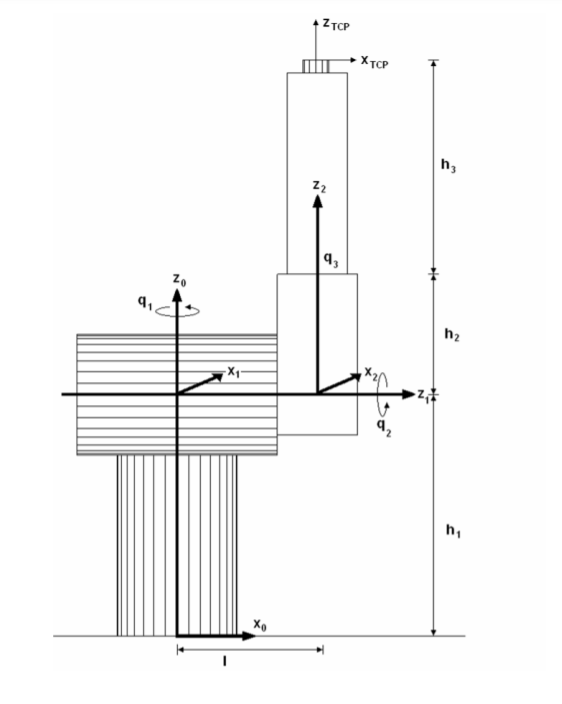

### b)

syms q1 q2 q3 h1 h2 h3 l 
theta = [q1 + pi/2; q2; -pi/2]

$$theta = \left(\begin{array}{c} q_{1}+\frac{\pi }{2}\\ q_{2}\\ -\frac{\pi }{2} \end{array}\right)$$

d = [h1; l; q3 + h2 + h3]

$$d = \left(\begin{array}{c} h_{1}\\ l\\ h_{2}+h_{3}+q_{3} \end{array}\right)$$

a = sym([0; 0; 0])

$$a = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

alpha = sym([pi/2; -pi/2; 0])

$$alpha = \left(\begin{array}{c} \frac{\pi }{2}\\ -\frac{\pi }{2}\\ 0 \end{array}\right)$$

### c)

Rz = @(t) [cos(t), -sin(t), 0;
           sin(t),  cos(t), 0;
           0, 0, 1];
Rx = @(t) [1, 0, 0;
           0, cos(t), -sin(t);
           0, sin(t),  cos(t)];

T_hom = @(R, p) [R, p; 
                 0, 0, 0, 1];

T_DH = @(theta, d, a, alpha) T_hom(Rz(theta), [0; 0; d]) * T_hom(Rx(alpha), [a; 0; 0]);

for i = 1:3
    fprintf("%d_T_%d = ", i-1, i)
    simplify(T_DH(theta(i), d(i), a(i), alpha(i)))
end

0_T_1 = 

$$ans = \left(\begin{array}{cccc} -\sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ 0 & 1 & 0 & h_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

1_T_2 = 

$$ans = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 0\\ 0 & -1 & 0 & l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

2_T_3 = 

$$ans = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 0\\ 0 & 0 & 1 & h_{2}+h_{3}+q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

sym T_03

$$ans = T_{03}$$

T_03 = eye(4)

T_03 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


for i = 1:3
    T_03 = T_03 * simplify(T_DH(theta(i), d(i), a(i), alpha(i)));
end
T_03

$$T\_03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & l\,\cos\left(q_{1}\right)+\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(h_{2}+h_{3}+q_{3}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & l\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(h_{2}+h_{3}+q_{3}\right)\\ 0 & \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & h_{1}+\cos\left(q_{2}\right)\,\left(h_{2}+h_{3}+q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$